# Continous Action Space Cart-Pole Environment with a policy gradient (PG) Agent 

Up until now we have used predefined environments, edited and modified the predefined environments. In this module we go through the **functions** that are required to create a reinforcement learning evnironment in MATLAB. The environment is a representation of what training ground for an agent. In order to navigate and get trained the agent needs to have information about -

- State / Observation function is a representation of environment parameters that help identify its position.

- Action function is to provide valid format of actions that an agent can take

- Reward function is to provide an agent with the feedback of agent's action 

- Step function if to guide agent in taking an action one at a time, and output the observations, rewards, and indicate whether the episode is complete

- Reset function is to initialize an environment for the agent's training process and to clear some parameters from the previous training eposides

- Environment input parameters that contains the environment constants

- A simulation function that will execute the steps in environment as per the input parameters

- Validation function to checking agent - environment interaction by calling the `reset` function and simulating the environment for one time step using `step`

- Constructor function: A function that creates an instance of the class

## Problem formulation

In the Cartpole environment there exists a pole pivoted the block of mass (Cart). The pole is unstable, but can be controlled by moving the pivot point under the center of mass. 

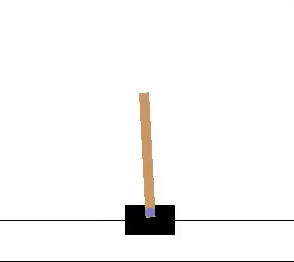

**Goal:** The goal is to keep the cartpole balanced by applying appropriate forces to a pivot point by moving the cart. That is to *is to prevent pole from falling over*

***Actions: ***Move the cart by applying force in range from –10 to 10 N.

***States: *** Cart position, cart velocity, pendulum angle, and pendulum angle derivative.

***Rewards: *** +1 is provided for every time step that the pole remains upright. A penalty of –10 is applied when the pole falls over

**Assumptions:**

- The upward balanced pendulum position is `0` radians, and the downward hanging position is `pi` radians.

- The pendulum starts upright with an initial angle that is between –0.05 and 0.05.

- The episode terminates if the pole is more than 12 degrees from vertical, or if the cart moves more than 2.4 m from the original position.

For more information on the environment please visit [this link.](https://www.mathworks.com/help/reinforcement-learning/ug/create-predefined-control-system-environments.html)

## **Creating the Environment**

The function to build the environment are built on top off eachother. We use [`rlFunctionEnv(obsInfo,actInfo,stepfcn,resetfcn)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.rlfunctionenv.html#d123e19373) to define a custom reinforcement learning environment. The inputs required for this functions are observation and action specifications, `obsInfo` and `actInfo`, respectively. The `StepFcn` and `ResetFcn` properties using MATLAB functions.

We begin by defining any parameters necessary for creating and simulating the environment. For detailed information on these properties visit [this link.](https://www.mathworks.com/help/reinforcement-learning/ug/create-predefined-control-system-environments.html)

Refer to the following table and create a structure named envConstants with following properties in it. And display its output.

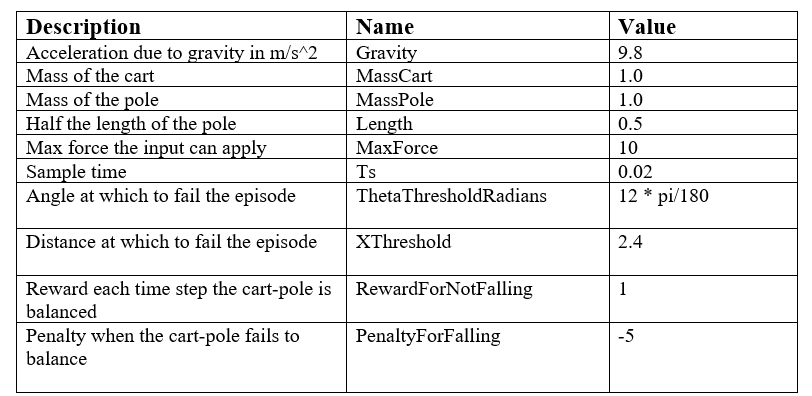

%Start your code here ~ 
envConstants.Gravity = 9.8;
envConstants.MassCart = 1.0;
envConstants.MassPole = 0.1;
envConstants.Length = 0.5;
envConstants.MaxForce = 10;
envConstants.Ts = 0.02;
envConstants.ThetaThresholdRadians = 12 * pi/180;
envConstants.XThreshold = 2.4;
envConstants.RewardForNotFalling = 1;
envConstants.PenaltyForFalling = -5;
envConstants

envConstants = struct with fields:
                  Gravity: 9.8000
                 MassCart: 1
                 MassPole: 0.1000
                   Length: 0.5000
                 MaxForce: 10
                       Ts: 0.0200
    ThetaThresholdRadians: 0.2094
               XThreshold: 2.4000
      RewardForNotFalling: 1
        PenaltyForFalling: -5


%Code ends here

## Defining obeservation and state parameters

State / Observation is a representation of environment parameters that help identify its position. The prameters are cart position, cart velocity, pendulum angle, and pendulum angle derivative.

We make use of function [`rlNumericSpec(dimension)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.util.rlnumericspec.html#d123e20014) to sprcify continuous action or observation data specifications for reinforcement learning environments. The input required in this case is Dimension of the data space, specified as a numeric vector.

Use the above function to and assign it to variable named ObservationInfo. 

%Start your code here ~ 1 line
ObservationInfo = rlNumericSpec([4 1]) % Creates vector with 3 observation

ObservationInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [4 1]
       DataType: "double"


%Code ends here

Change the Name property to CartPole States

%Start your code here ~ 1 line
ObservationInfo.Name = 'CartPole States';
%Code ends here

Add observation description as `x, dx, theta, dtheta`

%Start your code here ~ 1 line
ObservationInfo.Description = 'x, dx, theta, dtheta'

ObservationInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: "CartPole States"
    Description: "x, dx, theta, dtheta"
      Dimension: [4 1]
       DataType: "double"


%Code ends here

## Defining action space 

This defines valid format of actions that an agent can take, in this case it is move the cart by applying force in range from –10 to 10 N.

We make use of function [`rlFiniteSetSpec(elements)`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.util.rlfinitesetspec.html#d123e19052)`to specify `discrete action or observation data specifications for reinforcement learning environments. The input to this function can be

- Vector — Specify valid numeric values for a single action or single observation.

- Cell array — Specify valid numeric value combinations when you have more than one action or observation. Each entry of the cell array must have the same dimensions.

Use the above function to and assign it to variable named ActionInfo. 

%Start your code here ~ 1 line
ActionInfo = rlFiniteSetSpec([-10 10]) % 2 possible values of force in N

ActionInfo =   rlFiniteSetSpec with properties:

       Elements: [2×1 double]
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


%Code ends here

Change the Name property to CartPole Actions

%Start your code here ~ 1 line
ActionInfo.Name = 'CartPole Action';
%Code ends here

## Defining Reset Function

Reset function is to initialize an environment for the agent's training process. The reset function is used to reset the observation values to initial conditions or random conditions as specified by the user. This function must have the following signature.

`[InitialObservation,LoggedSignals] = myResetFunction()`

Parallely, to pass information from one step to the next, such as the environment state, use `LoggedSignals`

This functions must be in the current working folder or on the MATLAB path. Please go through the function file named ' myResetFunction.m '

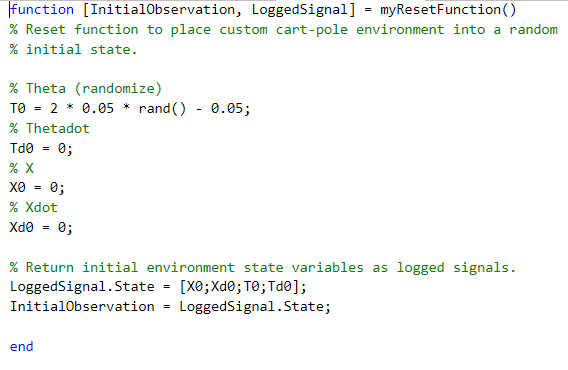

## Creating custom functions

Custom function are functions that can be passed onto step and reset function to perform any additional tasks that will help agent interact with the environment. To use these functions with rlFunctionEnv, you must use anonymous function handles.

ResetHandle = @()myResetFunction(arg1,arg2);

StepHandle = @(Action,LoggedSignals) myStepFunction(Action,LoggedSignals,arg1,arg2);

We make use of one such function to pass on the Properties of our Cart Pole problem to the step function. 

## Defining Step Function

Step function if to guide agent in taking an action one at a time, and output the observations, rewards, and indicate whether the episode is complete. This function must have the following signature. The new state is stored in `LoggedSignals` and returned as an output.

`[Observation,Reward,IsDone,LoggedSignals] = myStepFunction2(Action,LoggedSignals,``EnvConstants``)`

The sample cart-pole `step` function:

- Processes the input action.

- Evaluates the environment dynamic equations for one time step.

- Computes and returns the updated observations.

- Computes and returns the reward signal.

- Checks if the episode is complete and returns the `IsDone` signal as appropriate.

- Generates a notification that the environment has been updated.

This functions must be in the current working folder or on the MATLAB path. Please go through the function file named ' myStepFunction.m '

Create an anonymous function handle to the custom `step` function, passing `envConstants` as an additional input argument. Because `envConstants` is available at the time that `StepHandle` is created, the function handle includes those values. The values persist within the function handle even if you clear the variables.

StepHandle = @(Action,LoggedSignals) myStepFunction2(Action,LoggedSignals,envConstants);

Use the same `reset` function, specifying it as a function handle rather than by using its name.

ResetHandle = @() myResetFunction;

Once we have all the functions necessry to facillitate the interaction of agent with the environment we move head to compile everything into the MATLAN reinforcement learning environment object. For that we use the function [rlFunctionEnv(obsInfo,actInfo,stepfcn,resetfcn)](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.rlfunctionenv.html#d123e19373) to define a custom reinforcement learning environment.

This object is useful when we want custom environment that is beyond the predefined environments available with [rlPredefinedEnv](https://www.mathworks.com/help/reinforcement-learning/ref/rlpredefinedenv.html).

%Start your code here ~ 1 line
env = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle)

env =   rlFunctionEnv with properties:

          StepFcn: @(Action,LoggedSignals)myStepFunction2(Action,LoggedSignals,envConstants)
         ResetFcn: @()myResetFunction
    LoggedSignals: [1×1 struct]


%Code ends here

## Validating the Environment

Validating the environment is the process of making sure the interaction between the agent and environment as intended. Validating the environment makes sure that the agent learns policy in accordance. This can be done by reseting the environment and executing a step function to analyze the output. Set the random seed for reproducable results.

rng(0);
InitialObs = reset(env)

InitialObs =          0
         0
    0.0315
         0


## **Creating an Agent**

We have now seen how our environments behaves, let us move on to see how to construct and model a Deep Q learning agent. 

This can be done in following ways -

- Using Reinforcement Learning Designer app.

- Using RL toolbox agent functions (Like module 1)

- Modeling our own agent using Deep Designer App.

In the previous module we covered method 1- Using Reinforcement Learning Designer app for initiazing agent. In this module we will follow method 2 - using RL Toolbox agent functions

[`obsInfo`](https://www.mathworks.com/help/reinforcement-learning/ref/getobservationinfo.html#mw_109f65e1-0f64-414e-96b5-358f1b9bf30e_sep_mw_2f5d6ab3-a323-439f-8cf5-dd63b3ba5e01) `= getObservationInfo(`[`env`](https://www.mathworks.com/help/reinforcement-learning/ref/getobservationinfo.html#mw_109f65e1-0f64-414e-96b5-358f1b9bf30e_sep_mw_ce7c0a55-fd51-47fb-ba50-bcbce7b830d4)`)` extracts observation information from reinforcement learning environment `env`.

[`actInfo`](https://www.mathworks.com/help/reinforcement-learning/ref/getactioninfo.html#mw_3ef54c06-5144-4ef8-8137-de1b6be9a8ba_sep_mw_2f5d6ab3-a323-439f-8cf5-dd63b3ba5e01) `= getActionInfo(`[`env`](https://www.mathworks.com/help/reinforcement-learning/ref/getactioninfo.html#mw_5963825a-46b3-423b-8f12-3ad815f05b21)`)` extracts action information from reinforcement learning environment `env`.

% obtain observation and action specifications
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
agent = rlDQNAgent(obsInfo,actInfo);

We make use of rlTrainingOptions functions to specify the training parameters. And then 

For more information, see rlTrainingOptions.

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 500, ...
    'MaxStepsPerEpisode', 200, ...
    'Verbose', false, ...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',195,...
    'ScoreAveragingWindowLength',100); 

Train the agent using the [`train`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.agent.rlqagent.train.html) function.

trainingStats = train(agent,env,trainOpts);

To validate the performance of the trained agent, simulate it within the cart-pole environment. For more information on agent simulation, see [`rlSimulationOptions`](https://www.mathworks.com/help/reinforcement-learning/ref/rlsimulationoptions.html) and [`sim`](https://www.mathworks.com/help/reinforcement-learning/ref/rl.env.abstractenv.sim.html). 

simOptions = rlSimulationOptions('MaxSteps',500);
experience = sim(env,agent,simOptions);

In this module we learnt

- Functions reuired to build a custom MATLAB environment

- How to integrate function handle with step functions

- How to build a MATLAB environment using custom functions

In the next module we learn how to use Simulink RL block to train an RL Agent